# **Daisy World**

%% DEFINIZIONE DELLE COSTANTI
clear all

% Costante di Boltzmann
sigma = 5.67E-8;

% Albedo
a_b = 0.25;     % Margherite nere
a_w = 0.75;     % Margherite bianche
a_g = 0.5;      % Suolo

%
q = 20;

% Suolo occupabile
p = 1;

% 
f = 0.003265;

% Radiazione di fondo
S_0 = 1000;

%Areee iniziali occupate
area_b_ini = 0.2;   % Margherite nere
area_w_ini = 0.2;   % Margherite bianche

% Luminosità massima
max_l = 1.55;

% Luminosità minima
min_l = 0.7;

% Media per la perturbazione random (uniforme)
pert_rnd = 0.032;

## 1 - Radiazione incidente linearmente crescente

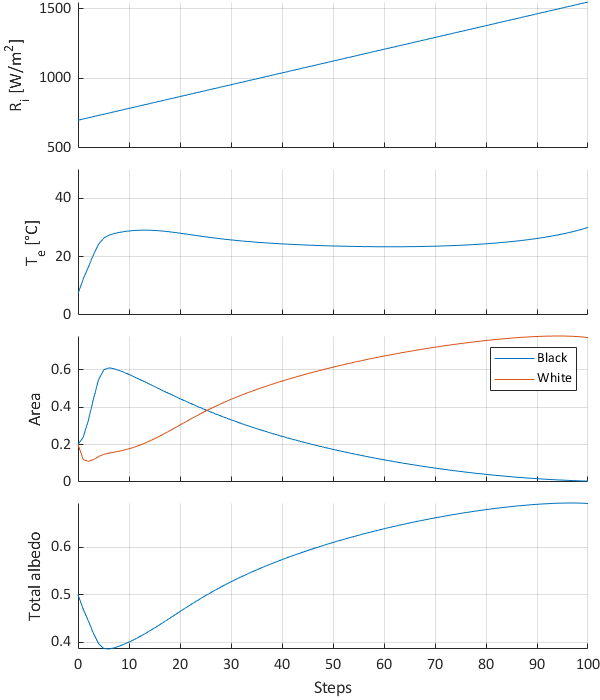

% Costruzione della luminosità
t = linspace(0,100,100);
l = linspace(min_l,max_l,length(t));

% Costruzione tasso di mortlità
mu = ones([1 length(t)])*0.2;      % Mortalità costante

% Simulazione
[T_e, area_b, area_w, area_g, albedo_p] = simulate_world( ...
t, S_0, l, ... 
a_b, a_w, a_g, ...
area_b_ini, area_w_ini, ...
q, mu, p, f, sigma,...
... % 1 per plottare
1);

## 2 - Radiazione  incidente come funzione periodica 

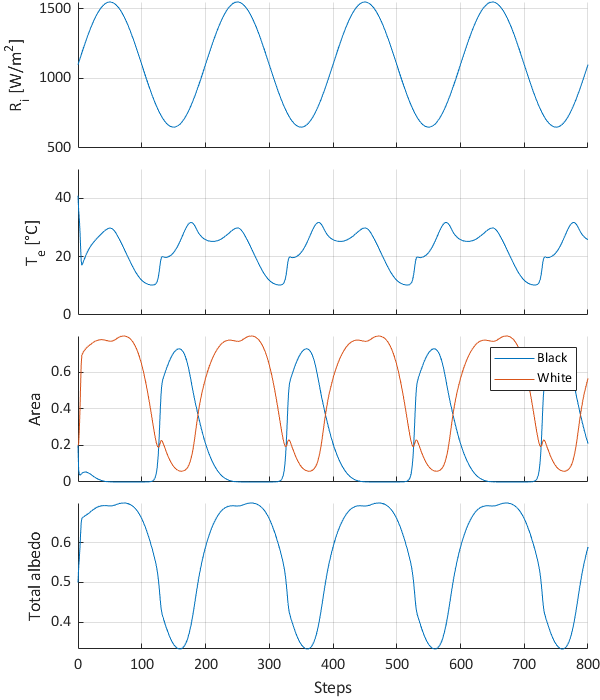

% Costruzione della luminosità
t = linspace(0,800,800);
l = 1.1 + 0.45*sin(2*pi*t/200);

% Costruzione tasso di mortlità
mu = ones([1 length(t)])*0.2;      % Mortalità costante

% Simulazione
[T_e_1, area_b_1, area_w_1, area_g_1, albedo_p_1] = simulate_world( ...
t, S_0, l, ... 
a_b, a_w, a_g, ...
area_b_ini, area_w_ini, ...
q, mu, p, f, sigma,...
... % 1 per plottare
1);

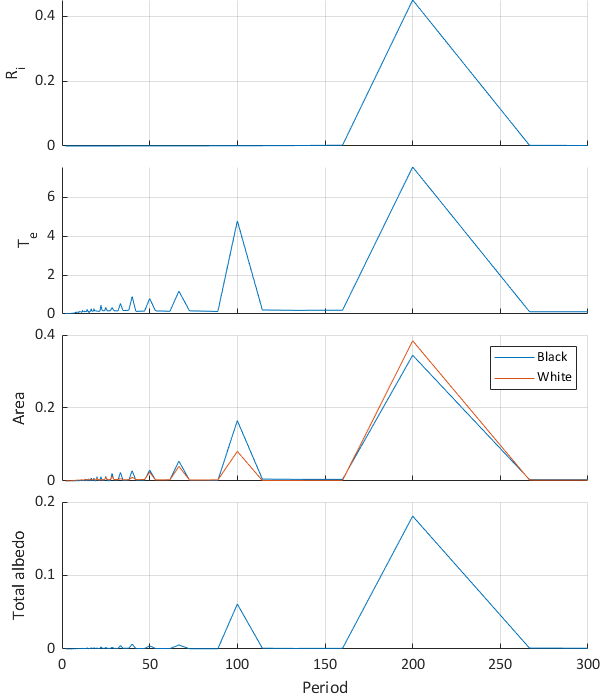

% Analisi delle periodicità con fourier
[l_f,T_e_f, area_b_f, area_w_f, area_g_f, albedo_p_f, frec] = fourier_analysis(...
    l, T_e_1, area_b_1, area_w_1, area_g_1, albedo_p_1, 1);

## 3 - Radiazione incidente linearmente crescente con disturbo

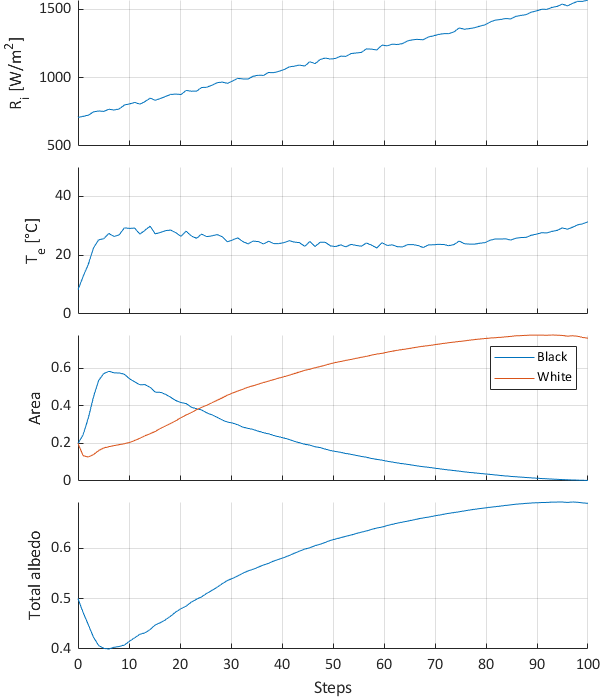

% Costruzione della luminosità linearmente crescente
t = linspace(0,100,100);
l = linspace(min_l,max_l,length(t));

% Costruzione tasso di mortlità
mu = ones([1 length(t)])*0.2;      % Mortalità costante

% Aggiunge un po' di rumore random (uniforme)
x = random('uniform',0,pert_rnd,[1 length(t)]);

% Componsizione dei rumori col segnale
l = l + x;

% Simulazione
[T_e, area_b, area_w, area_g, albedo_p] = simulate_world( ...
t, S_0, l, ... 
a_b, a_w, a_g, ...
area_b_ini, area_w_ini, ...
q, mu, p, f, sigma,...
... % 1 per plottare
1);

## 4 - Radiazione  incidente come funzione periodica con disturbo

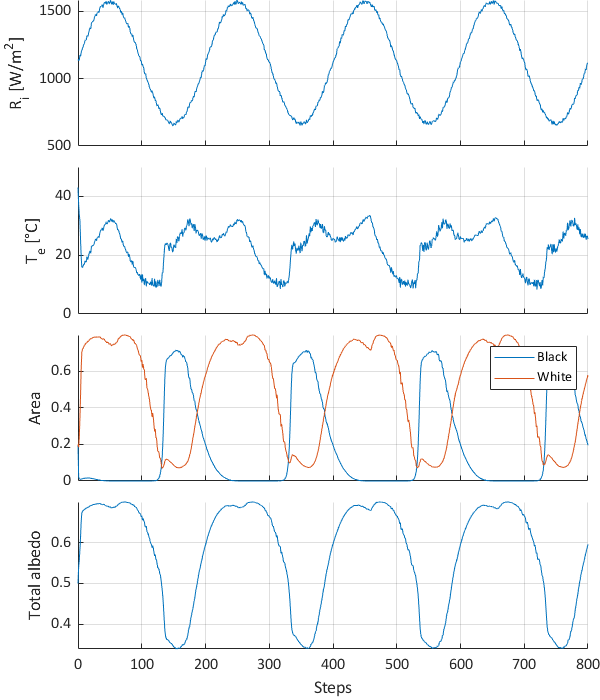

% Costruzione della luminosità
t = linspace(0,800,800);
l = 1.1 + 0.45*sin(2*pi*t/200);

% Costruzione tasso di mortlità
mu = ones([1 length(t)])*0.2;      % Mortalità costante

% Aggiunge un po' di rumore random (uniforme)
x = random('uniform',0,pert_rnd,[1 length(t)]);

% Componsizione dei rumori col segnale
l = l + x;

% Simulazione
[T_e, area_b, area_w, area_g, albedo_p] = simulate_world( ...
t, S_0, l, ... 
a_b, a_w, a_g, ...
area_b_ini, area_w_ini, ...
q, mu, p, f, sigma,...
... % 1 per plottare
1);

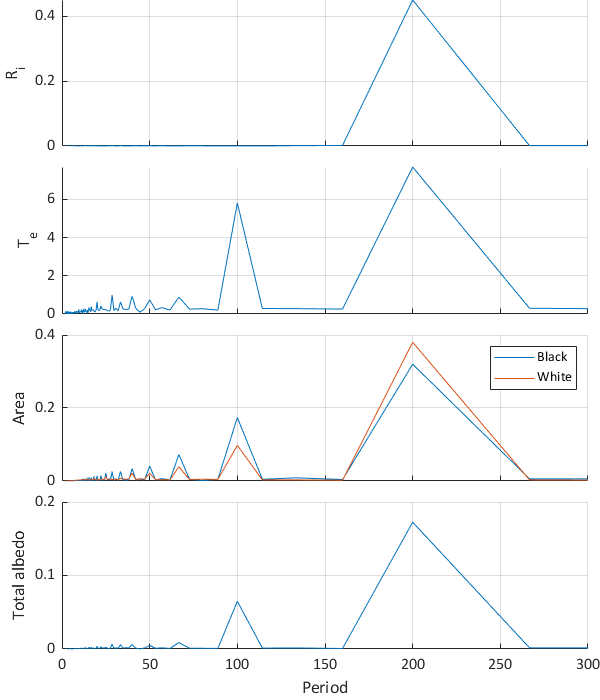

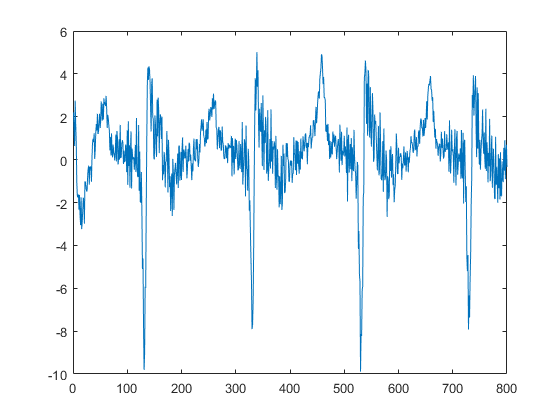


% Analisi delle periodicità con fourier
[l_f,T_e_f, area_b_f, area_w_f, area_g_f, albedo_p_f, frec] = fourier_analysis(...
l, T_e, area_b, area_w, area_g, albedo_p, ...
... % 1 per plottare
1);